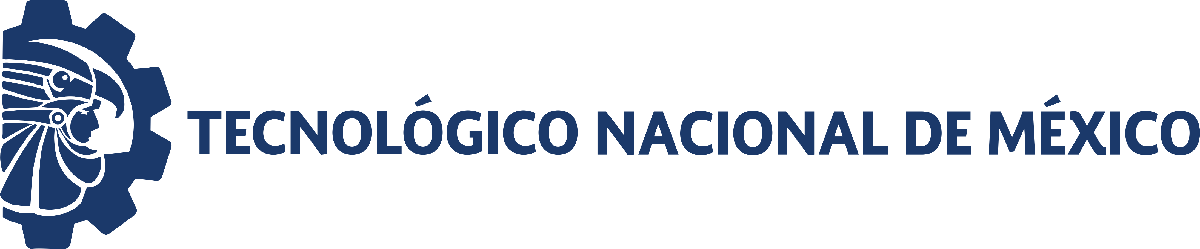                                 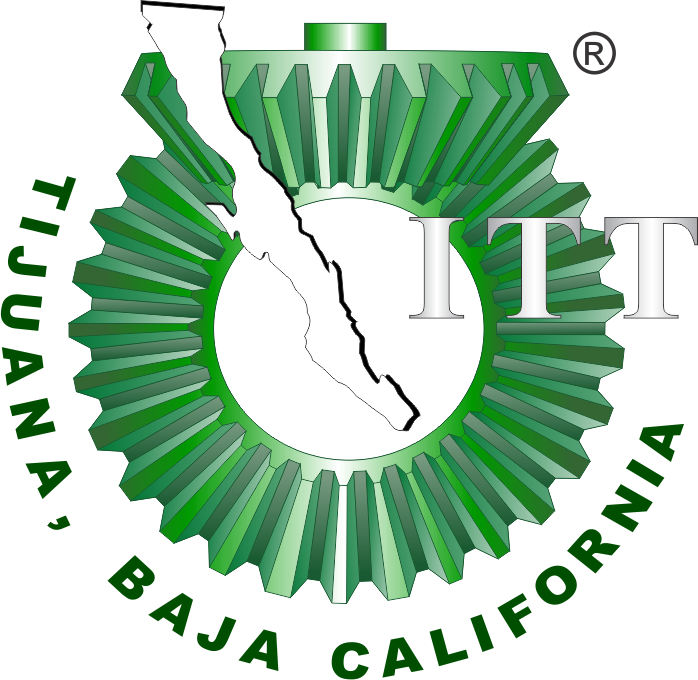

# Práctica: Regeneración de glóbulos rojos [Sistema de EDOs]

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

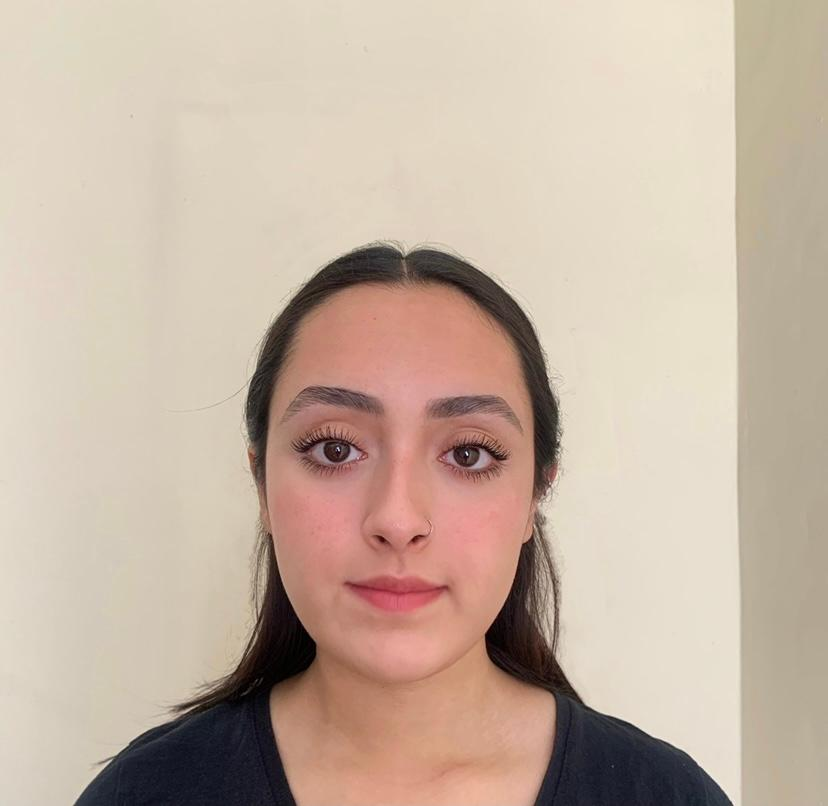 

Nombre del alumno: Jovita Maria Fernanda Antunez Rubio

Número de control: 22211745

Correo institucional: L22211745**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = 180; %Tiempo de la simulación en días
file = 'Sistema5_4';
dt= 1e-3; %Intervalo de integración para el métodos de solución por diferencias finitas
n = round(tend/dt); %Cantidad de iteraciones para el método numérico

%Condiciones inicales base para cada px
x1_0= 59; x2_0=44; x3_0= 855;
%Parámetros particulares para cada px
gamma = [0.769; 0.388; 0.510; 0.590; 0.262; 0.324;0.356; 0.089; 0.243; 0.057];
beta= [1.650; 0.867; 1.617; 2.615; 1.518; 2.676; 0.891; 2.557; 0.925;0.879];

seed=22211745; %Semilla para asegurar reproducibilidad
rng(seed,'twister')
%Intervalo de la condiciones iniciales
xmin = 0.99; max=1.01;
interval =  xmin + (max - xmin).*rand (numel(gamma),1);

%Condiciones iniciales para cada px
x1_0 = x1_0*interval; disp('x1(0)=');disp(x1_0');...
x2_0 = x2_0*interval; disp('x2(0)=');disp(x2_0');...
x3_0 = x3_0*interval; disp('x3(0)=');disp(x3_0');

x1(0)=
   59.4478   58.8950   58.6617   58.9564   58.5419   59.2753   58.7772   58.6727   59.1264   58.8525



x2(0)=
   44.3340   43.9217   43.7477   43.9675   43.6583   44.2053   43.8338   43.7559   44.0943   43.8900



x3(0)=
  861.4899  853.4778  850.0971  854.3679  848.3609  858.9899  851.7707  850.2573  856.8315  852.8619



##  Caso: Sin transfusión sanguínea [u(t)=0]

u = zeros(n+1,1); %No hay transfusión
fig=1;
for i=1:10
    [t,x1,x2,x3]= system(x1_0(i),x2_0(i), x3_0(i), beta(i), gamma(i),u, dt, tend);
    plotdata(t,x1,x2,x3,fig)
end 

## Caso: Con transfusión sanguínea 

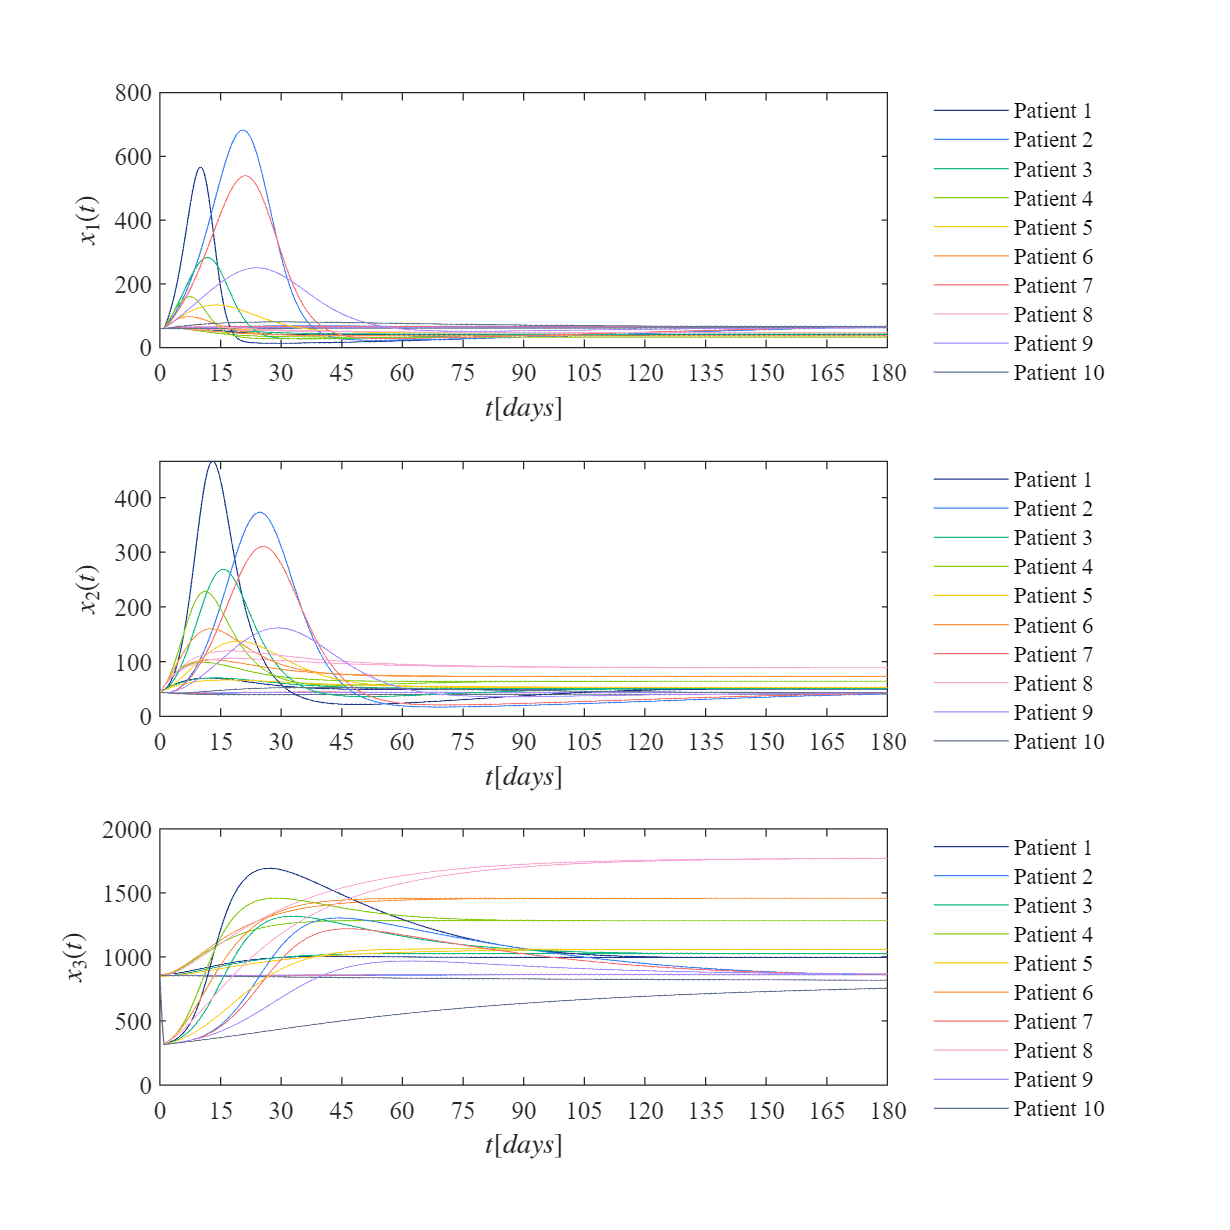

u= zeros(n+1,1); 
u(1:1000) = 1;
fig = 2;
for i = 1:10
    [t,x1,x2,x3]= system(x1_0(i),x2_0(i),x3_0(i),beta(i),gamma(i),u,dt,tend);
    plotdata(t,x1,x2,x3,fig)
end

## Función: Modelo matemático


$$\left.{\dot{x} }_1 =\beta {\left(X\right.}_0 -k_1 x_1 \right)+\frac{\gamma \left(B_{\mathrm{ase}} -x_3 \right)\left(1-u\left(t\right)\right)x_1 }{B_{\mathrm{ase}} }$$



$$\begin{array}{l}
{\dot{x} }_2 =\beta \left(k_1 x_1 -k_2 x_2 \right)\\
{\dot{x} }_3 =\beta \left(k_2 x_2 -\alpha x_3 \right)-u\left(t\right)x_3 
\end{array}$$


function [t,x1,x2,x3]= system (x1_0,x2_0,x3_0,beta,gamma,u,dt,tend)
%Parámetros fijod del sist.
Base = 885.42; x0=7.3785; k1= 0.125; k2= 0.1667; alpha= 0.00833;
t= (0:dt:tend)';
n= round(tend/dt);
x1= zeros(n+1,1); x1(1)=x1_0;
x2= zeros(n+1,1); x2(1)=x2_0;
x3= zeros(n+1,1); x3(1)=x3_0;

for i = 1:n %Método de Euler (diferencias finitas)
    x1(i+1)= x1(i)+ (beta*(x0-k1*x1(i))+ gamma*(Base-x3(i))*(1-u(i))*x1(i)/Base)*dt;
    x2(i+1)= x2(i)+(beta*k1*x1(i)-k2*x2(i))*dt;
    x3(i+1)= x3(i)+ (beta*(k2*x2(i)-alpha*x3(i))-u(i)*x3(i))*dt;
end
end


## Función: Soluciones en el tiempo

function plotdata(t,x1,x2,x3,fig)
set(figure(fig),'Color', 'w')
set (gcf,'Units', 'Centimeters', 'Position', [1,1,20,20])
    mycolors= [30, 58, 138; 
        59, 130, 246; 
        16, 185, 129;
        132, 204, 22;
        250, 204, 21;
        251, 146, 60; 
        248, 113, 113;
        249, 168, 212;
        167, 139, 250; 
        100, 116, 139]/255;
subplot (3,1,1)
hold on; grid off; box on; colororder(mycolors)

plot(t,x1)
xlabel('$t [days]$', 'Interpreter','latex', 'FontSize', 10)
ylabel('$x_1(t)$', 'Interpreter','latex', 'FontSize', 10)
xlim ([0 180]); xticks(0:15:180);
L = legend('Patient 1','Patient 2','Patient 3','Patient 4','Patient 5','Patient 6','Patient 7','Patient 8','Patient 9','Patient 10');
    set(L,'FontSize',9,'Box','Off','Location','NorthEastOutside');
set(gca, 'FontName', 'Times New Roman', 'FontSize', 10)

subplot (3,1,2)
hold on; grid off; box on; colororder(mycolors)
plot(t,x2)
xlabel('$t [days]$', 'Interpreter','latex', 'FontSize', 10)
ylabel('$x_2(t)$', 'Interpreter','latex', 'FontSize', 10)
xlim ([0 180]); xticks(0:15:180);
L = legend('Patient 1','Patient 2','Patient 3','Patient 4','Patient 5','Patient 6','Patient 7','Patient 8','Patient 9','Patient 10');
    set(L,'FontSize',9,'Box','Off','Location','NorthEastOutside');
set(gca, 'FontName', 'Times New Roman', 'FontSize', 10)

subplot (3,1,3)
hold on; grid off; box on; colororder(mycolors)
plot(t,x3)
xlabel('$t [days]$', 'Interpreter','latex', 'FontSize', 10)
ylabel('$x_3(t)$', 'Interpreter','latex', 'FontSize', 10)
xlim ([0 180]); xticks(0:15:180);
L = legend('Patient 1','Patient 2','Patient 3','Patient 4','Patient 5','Patient 6','Patient 7','Patient 8','Patient 9','Patient 10');
    set(L,'FontSize',9,'Box','Off','Location','NorthEastOutside');
set(gca, 'FontName', 'Times New Roman', 'FontSize', 10)

if fig== 1
    exportgraphics(gcf,'Caso sin transfusion.pdf','ContentType','Vector')
    exportgraphics(gcf,'Caso sin transfusion.png','ContentType','Vector')
elseif fig==2
    exportgraphics(gcf,'Caso con transfusion.pdf','ContentType','Vector')
    exportgraphics(gcf,'Caso con transfusion.png','ContentType','Vector')
end
end

